# Peak Prominences

Create a signal that consists of a sum of bell curves riding on a full period of a cosine. Specify the location, height, and width of each curve.

x_length = 1000;
x = linspace(0,1,x_length);

base = - 4*cos(2*pi*x);

Pos = [1 2 3 5 7 8]/10;
Hgt = [3 7 5 5 4 5];
Wdt = [1 3 3 4 2 3]/100;

lengthPos = length(Pos);
Gauss = zeros(lengthPos, x_length);
for n = 1:length(Pos)
    Gauss(n,:) =  - Hgt(n)*exp(-((x - Pos(n))/Wdt(n)).^2);
end

PeakSig = sum(Gauss)+base;


Plot the individual curves and their sum.

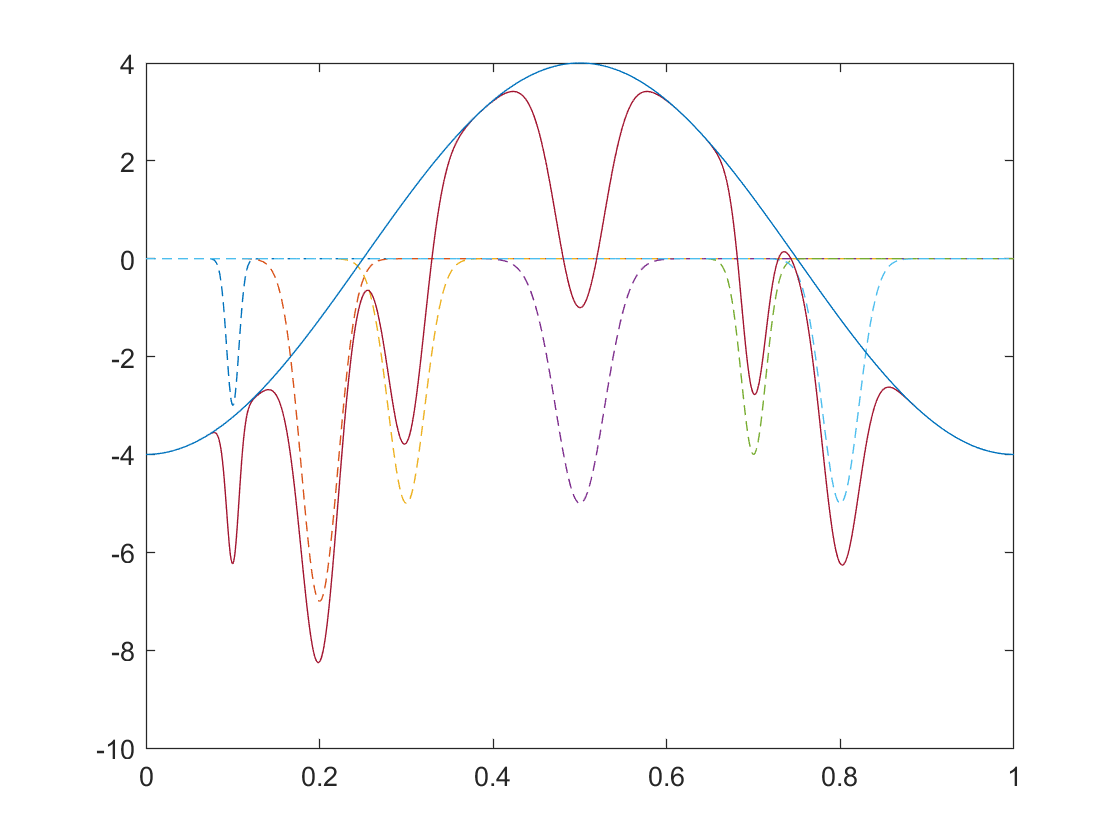

plot(x,Gauss,'--',x,PeakSig,x,base)

Use `findpeaks` to locate and plot the peaks that have a prominence of at least 4.

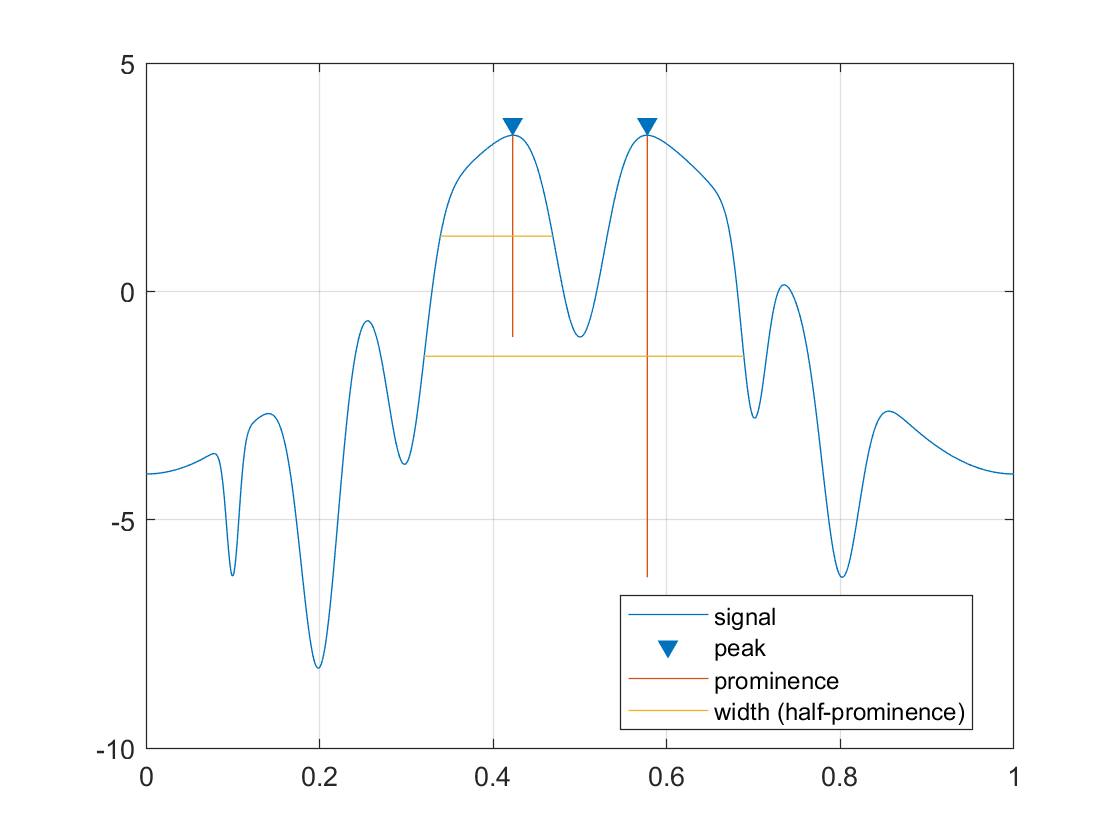

findpeaks(PeakSig,x,'MinPeakProminence',4,'Annotate','extents')

**Note that the second prominence is wrong. This denotes a bug within findpeaks function.**

The highest and lowest peaks are the only ones that satisfy the condition.

Display the prominences and the widths at half prominence of all the peaks.

[pks,locs,widths,proms] = findpeaks(PeakSig,x);
widths

widths =     0.0317    0.0608    0.0429    0.1296    0.3683    0.0465    0.0702


proms

proms =     0.4472    3.5578    3.1448    4.4171    9.6789    2.9191    1.3753
